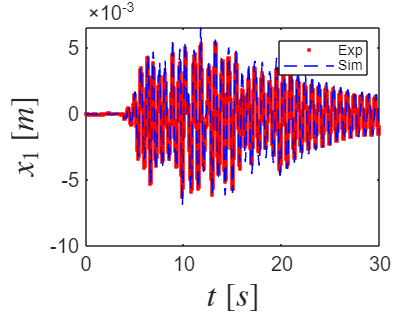

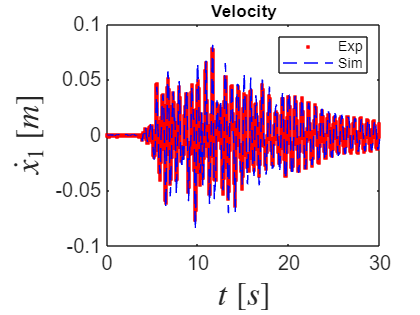

%Graficar

load('datosFiltradosSismoYOct8.mat','ab','xr','vr','t'); %datos de los experimentos

best=1000;
ibest=0;
for i=1:30
    txt='parametros_corrida_'+ string(i) +'.mat';
    load (txt);
    if fval < best
        best=fval;
        ibest=i;
    end
end

txt='parametros_corrida_'+ string(ibest) +'.mat';
load (txt);

%Masas de la estructura
M=diag([11.773 9.17 9.14 9.12 9.08]); %Masas sin conectar amortiguador
%M=[12.5 9.17 9.15 9.11 9.08];  %Masas con amortiguador
m1=M(1,1); m2=M(2,2); m3=M(3,3); m4=M(4,4); m5=M(5,5);

Mi=inv(M);
l=ones(5,1);

Cs=[c1+c2, -c2,    0,    0,   0;
    -c2,  c2+c3, -c3,    0,   0;
    0,     -c3,  c3+c4, -c4,  0;
    0,      0,   -c4,   c4+c5,-c5;
    0,      0,     0,   -c5,   c5];

Ks=[k1+k2, -k2,   0,    0,    0;
   -k2,  k2+k3, -k3,   0,    0;
     0,  -k3,  k3+k4, -k4,   0;
     0,   0,    -k4,  k4+k5,-k5;
     0,   0,      0,   -k5,  k5];
n=5;

%Space-state
A = [zeros(n) eye(n); -Mi*Ks -Mi*Cs];
B = [zeros(n,1); -l];
C = eye(2*n);

%Dimensiones
nx=size(A,1);
nu=size(B,2);
ny=size(C,1);
D = zeros(ny,nu);

x0=zeros(nx,1); %Initial conditions
sys=ss(A,B,C,D);
Ye=lsim(sys,ab,t,x0,'foh');

piso=1;
graficas(piso,Ye,xr,vr,t)

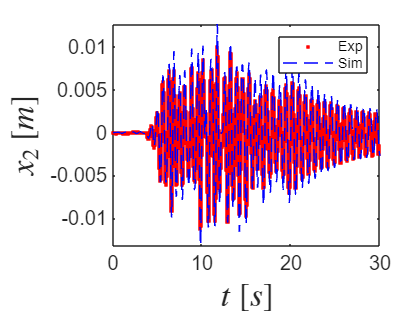

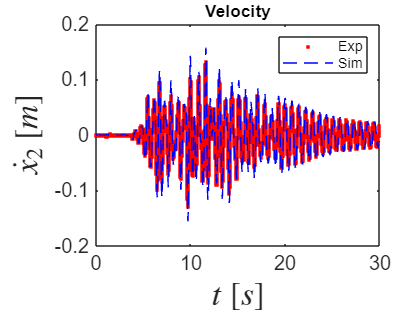


piso=2;
graficas(piso,Ye,xr,vr,t)

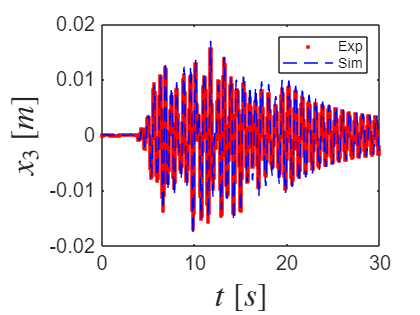

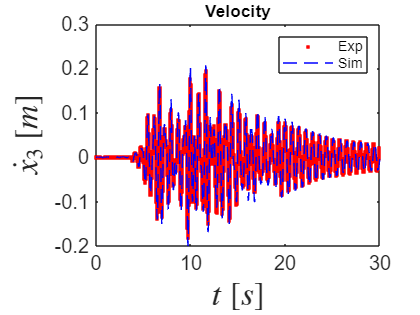


piso=3;
graficas(piso,Ye,xr,vr,t)

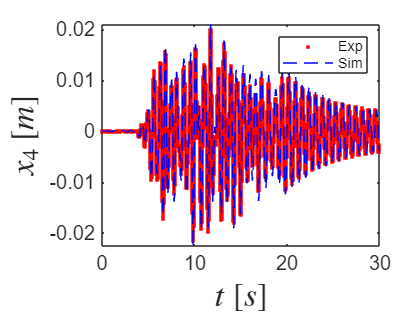

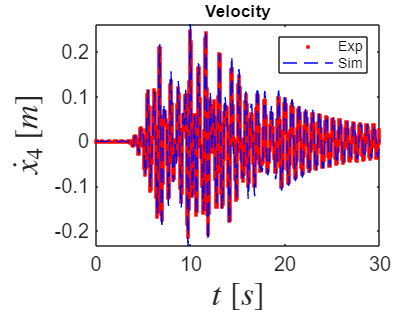


piso=4;
graficas(piso,Ye,xr,vr,t)

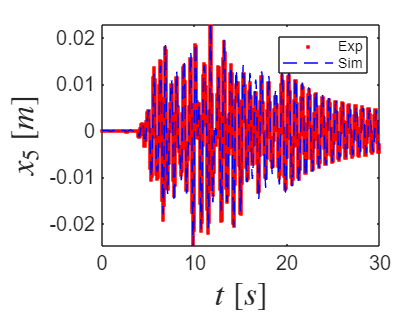

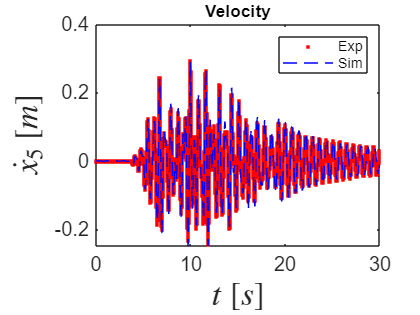


piso=5;
graficas(piso,Ye,xr,vr,t)


function graficas(piso,Ye,xr,vr,t)
    
    %Desplazamiento
    figure()
    plot(t,xr(:,piso),'.r',t,Ye(:,piso),'--b')
    ax=gca;
    ax.XAxis.FontSize = 12;
    ax.YAxis.FontSize = 12;
    xlabel({'$t$ [$s$]'},'Interpreter','latex','FontWeight','bold','FontSize',20)
    txt='$x_'+ string(piso) +'$ [$m$]';
    ylabel(txt,'Interpreter','latex','FontWeight','bold','Fontsize',20)
    legend('Exp','Sim')

    %Velocidad
    figure()
    plot(t,vr(:,piso),'.r',t,Ye(:,piso+5),'--b')
    ax=gca;
    ax.XAxis.FontSize = 12;
    ax.YAxis.FontSize = 12;
    xlabel({'$t$ [$s$]'},'Interpreter','latex','FontWeight','bold','FontSize',20)
    txt='$\dot{x}_'+ string(piso) +'$ [$m$]';
    ylabel(txt,'Interpreter','latex','FontWeight','bold','Fontsize',20)
    legend('Exp','Sim')
    title('Velocity')

    %Error
    % figure()
    % plot(t,(Ye(:,piso)-xr(:,piso)).^2)
    % ax=gca;
    % ax.XAxis.FontSize = 12;
    % ax.YAxis.FontSize = 12;
    % xlabel({'$t$ [$s$]'},'Interpreter','latex','FontWeight','bold','FontSize',20)
    % txt='$e_'+ string(piso) +'$ [$m$]';
    % ylabel(txt,'Interpreter','latex','FontWeight','bold','Fontsize',20)

end